# Figure 1: Superfine Contour

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])


load('Figure1_Data_S_EE=0.028_S_II=0.12_S_Elgn=0.070_7D_HPC_S_IlgnInd3_rI_L6Ind3.mat','ContourData_7D')

S_EEtest = [0.020 0.024 0.028];
S_IItest = [0.06  0.09  0.12  0.15  0.18];
S_ElgnInd = 3;
S_IlgnInd = 3; % $(seq 2 4)
rI_L6Ind = 3;  % 3 6
S_EEInd = 3;
S_IIInd = 3;

S_EE = S_EEtest(S_EEInd);
S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
S_Elgn=S_Elgntest(S_ElgnInd);

S_II = S_IItest(S_IIInd);
S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);

## Fine Contours

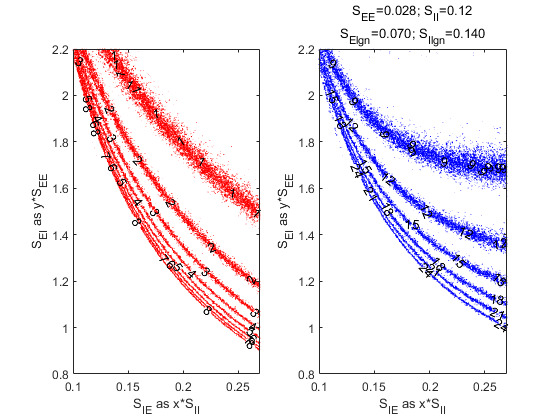

subplot 121
CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
CurrentUnsteady = squeeze(ContourData_7D.ConvIndi(:,: ));
CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: ));
CurrentFrE(CurrentFrE<eps) = nan; CurrentFrE(CurrentBlowup == 1) = nan;
CurrentFrE(~CurrentUnsteady) = nan;

CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
CurrentFrI(CurrentFrI<eps) = nan; CurrentFrI(CurrentBlowup == 1) = nan;
CurrentFrI(~CurrentUnsteady) = nan;
[C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrE,[1:8 ],'ShowText','on','color','r');
clabel(C1,h1,'FontSize',10,'Color','k')
xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')

subplot 122
[C2,h2]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrI,[3:3:24],'ShowText','on','color','b');
clabel(C2,h2,'FontSize',10,'Color','k')

title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
               S_EE,        S_II,        S_Elgn,        S_Ilgn))
xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')